format("short","g")
clear
clc

%defining constants:
km=5.7;
mF=0.8;
mM=1e-5;
mL=0.3;
dF=6; 
kF=6000;
db=1;
kb=800;
d=3;

## Task1

a)

%defining state matrices:
A=[-(db+d)/mL 0 d/mL 0 db/mL kb/mL;
      1    0      0   0   0      0;
      d/mF 0 -(dF+d)/mF kF/mF 0  0;
      0    0   -1         0   0  0;
      db/mM 0  0  0 -db/mM  -kb/mM;
      -1   0      0   1   0      0];

B=[0; 0; -km/mF; 0; km/mM; 0];

C=[0 1 0 0 0 0;
   0 0 0 1 0 0;
   0 0 0 0 0 1];

D=[0; 0; 0];

b)

%to get tf for out xload
[num1, den1]=ss2tf(A,B,C(1,:),D(1,:));
sys1=tf(num1, den1)

sys1 =
 
           1.9e06 s^3 + 1.425e07 s^2 + 1.425e10 s + 0.0002255
  --------------------------------------------------------------------
  s^6 + 1e05 s^5 + 2.135e06 s^4 + 7.576e08 s^3 + 7.52e09 s^2 + 1.099 s
 
Continuous-time transfer function.



%to get tf for out xframe
[num2, den2]=ss2tf(A,B,C(2,:),D(2,:));
sys2=tf(num2, den2)

sys2 =
 
    7.125 s^4 + 7.126e05 s^3 + 1.9e04 s^2 - 1.393e-06 s - 2.384e-24
  --------------------------------------------------------------------
  s^6 + 1e05 s^5 + 2.135e06 s^4 + 7.576e08 s^3 + 7.52e09 s^2 + 1.099 s
 
Continuous-time transfer function.



%to get tf for out xmotor
[num3, den3]=ss2tf(A,B,C(3,:),D(3,:));
sys3=tf(num3, den3)

sys3 =
 
          -1.9e06 s^3 - 1.354e07 s^2 - 1.425e10 s + 0.0005461
  --------------------------------------------------------------------
  s^6 + 1e05 s^5 + 2.135e06 s^4 + 7.576e08 s^3 + 7.52e09 s^2 + 1.099 s
 
Continuous-time transfer function.



c)

%getting poles of each system
P1=pole(sys1)

P1 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


P2=pole(sys2)

P2 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


P3=pole(sys3)

P3 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


%getting eigenvalues for each system
e1=eig(sys1)

e1 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


e2=eig(sys2)

e2 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


e3=eig(sys3)

e3 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


d)

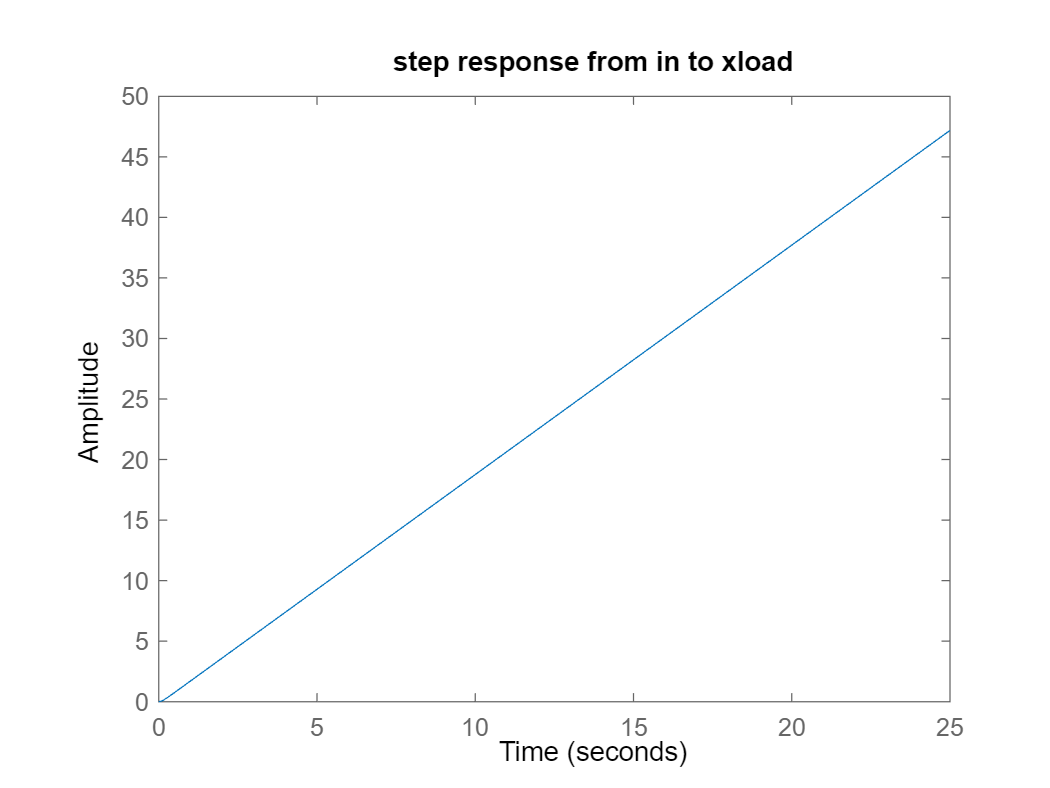

%plotting step responses for each system
figure()
step(sys1)
title("step response from in to xload")

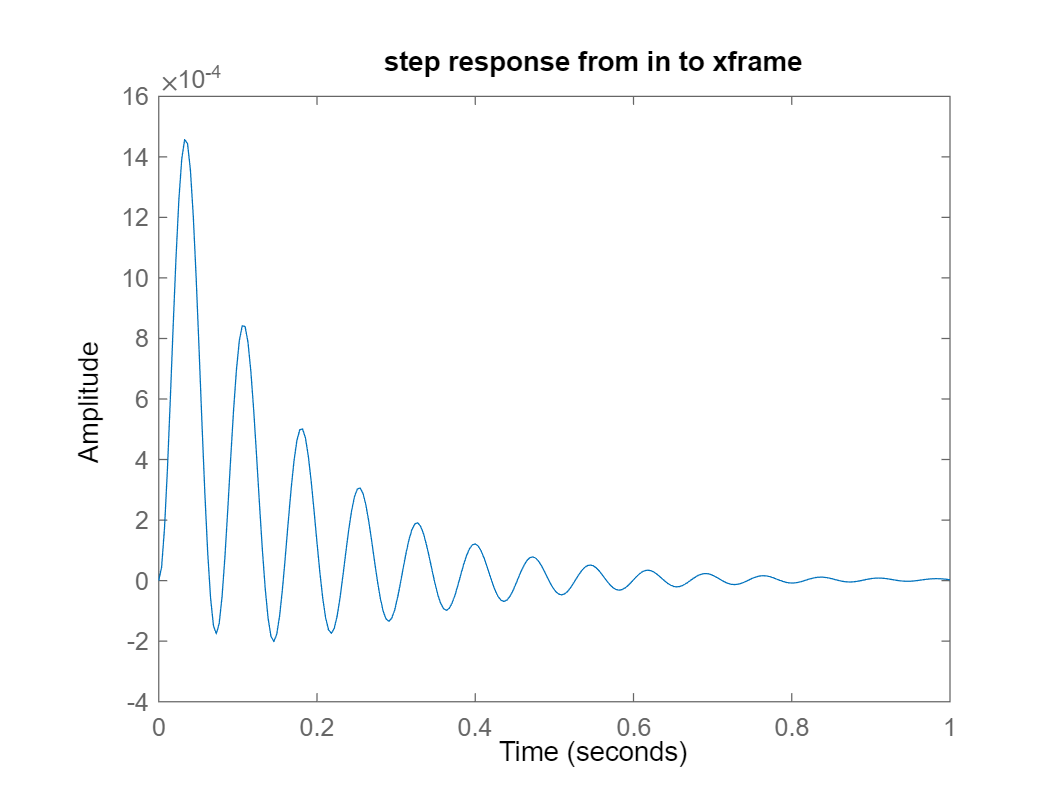

figure()
step(sys2)
title("step response from in to xframe")

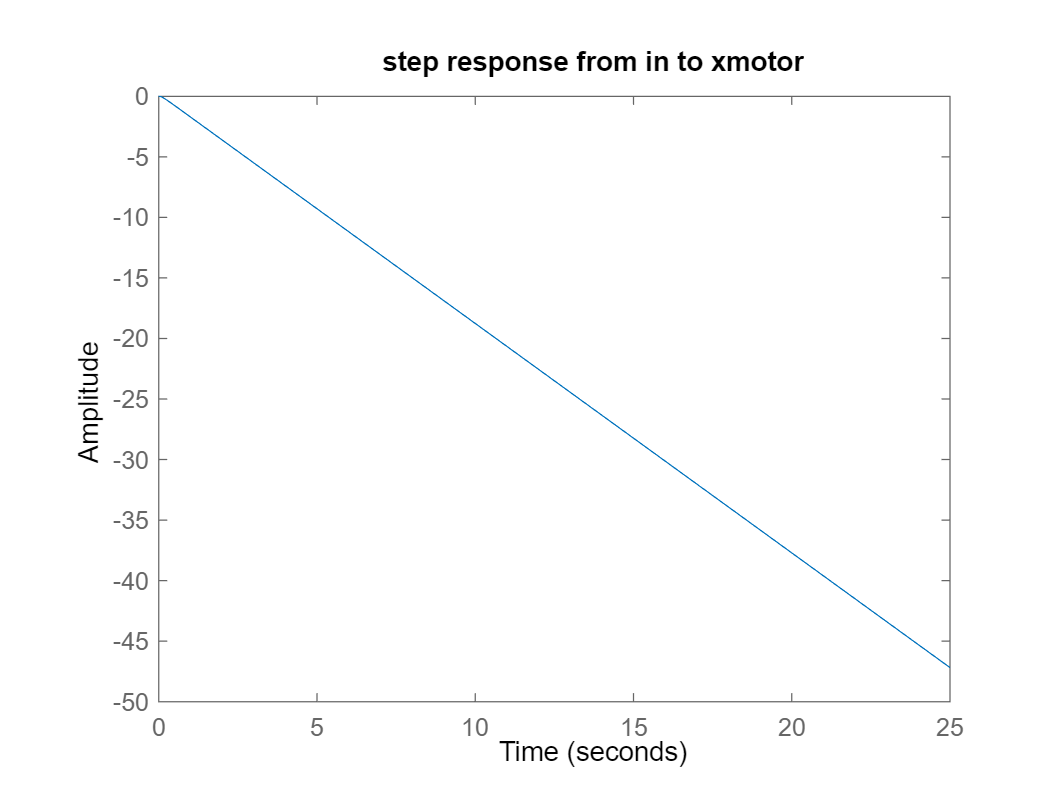

figure()
step(sys3)
title("step response from in to xmotor")

e)

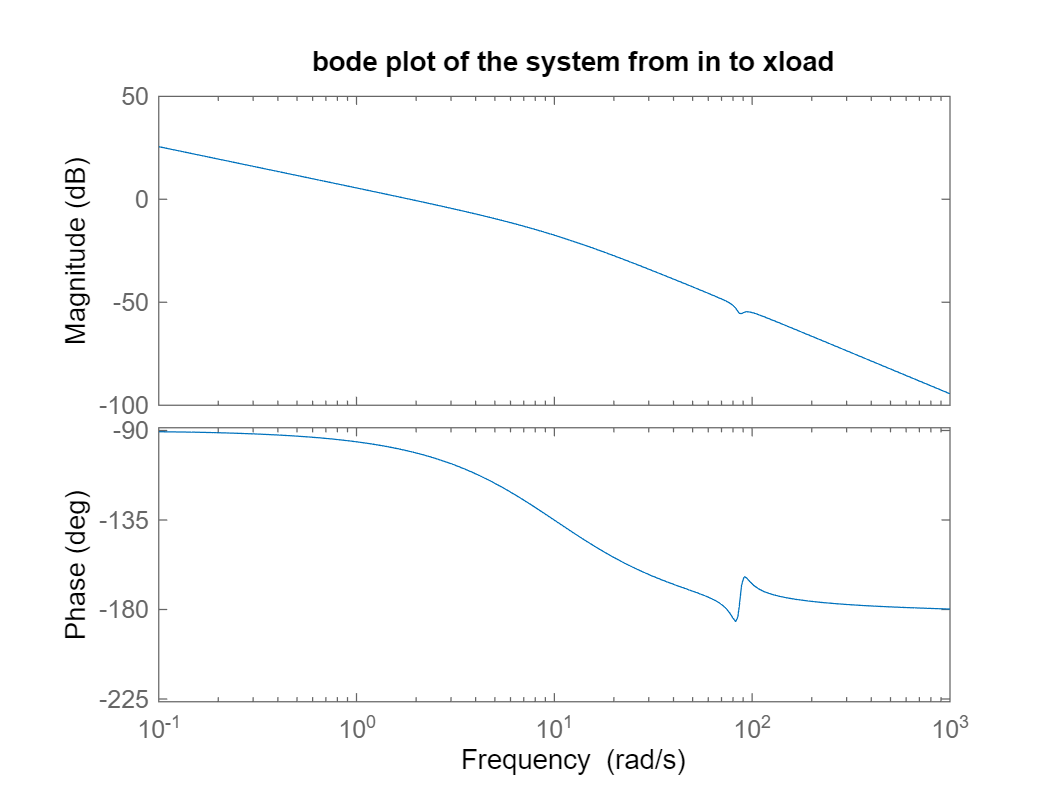

%plotting bode plots for each system
figure()
bode(sys1)
title("bode plot of the system from in to xload")

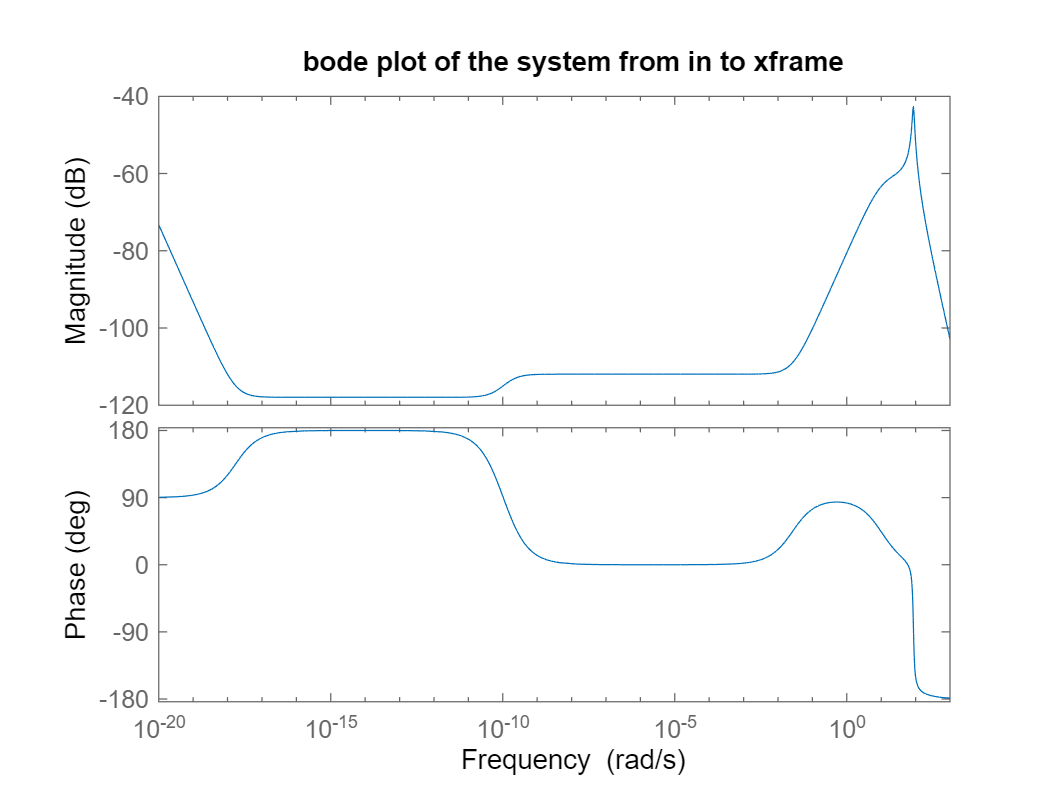

figure()
bode(sys2)
title("bode plot of the system from in to xframe")

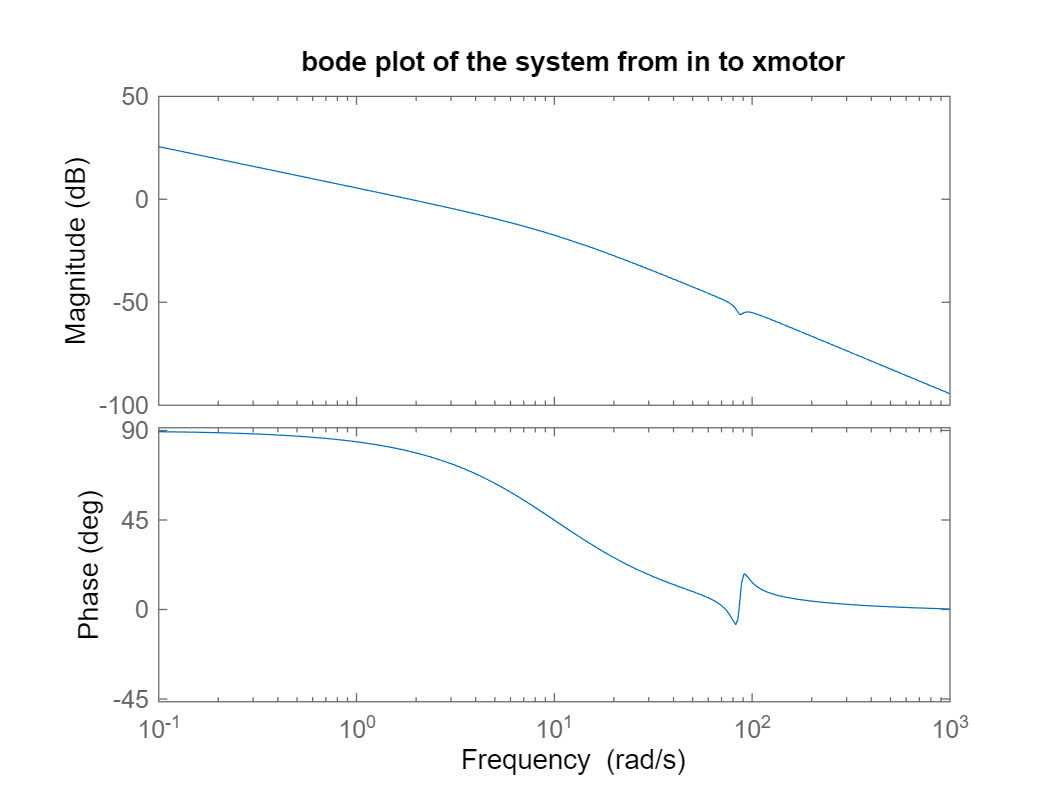

figure()
bode(sys3)
title("bode plot of the system from in to xmotor")

## Task2

%checking controllability of the system
Cc=ctrb(A,B);
rank_of_Cc=rank(Cc)

rank_of_Cc =      1


rank(A)

ans =      4


%checking observability for each output
%xload
O1 = obsv(A, C(1,:));
rank_of_O1 = rank(O1) 

rank_of_O1 =      3


%xframe
O2 = obsv(A, C(2,:));
rank_of_O2 = rank(O2) 

rank_of_O2 =      3


%xmotor
O3 = obsv(A, C(3,:));
rank_of_O3 = rank(O3) 

rank_of_O3 =      3


all the systems are unobservable

## Task3

a)

%the 6th order sisio system is sys1 defined above

%poles
P1

P1 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


%zeros
Z=zero(sys1)

Z =       -3.7501 +     86.523i
      -3.7501 -     86.523i
  -1.5827e-14 +          0i


b)

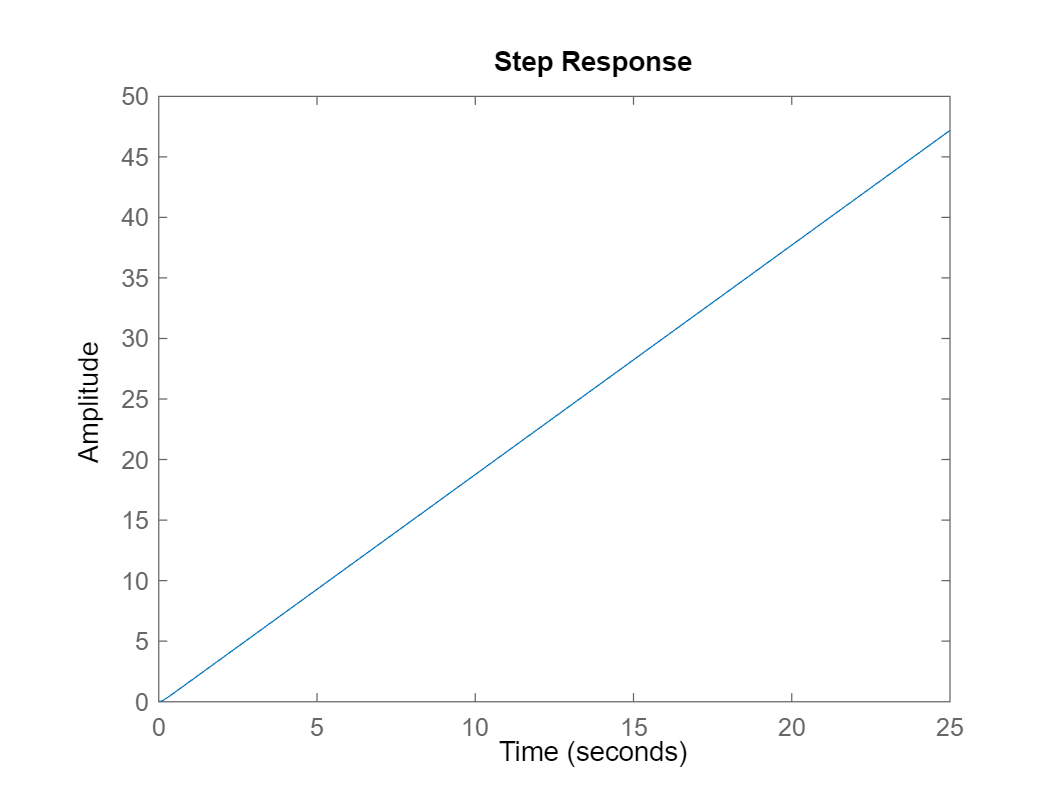

%plotting step and bode
figure()
step(sys1)

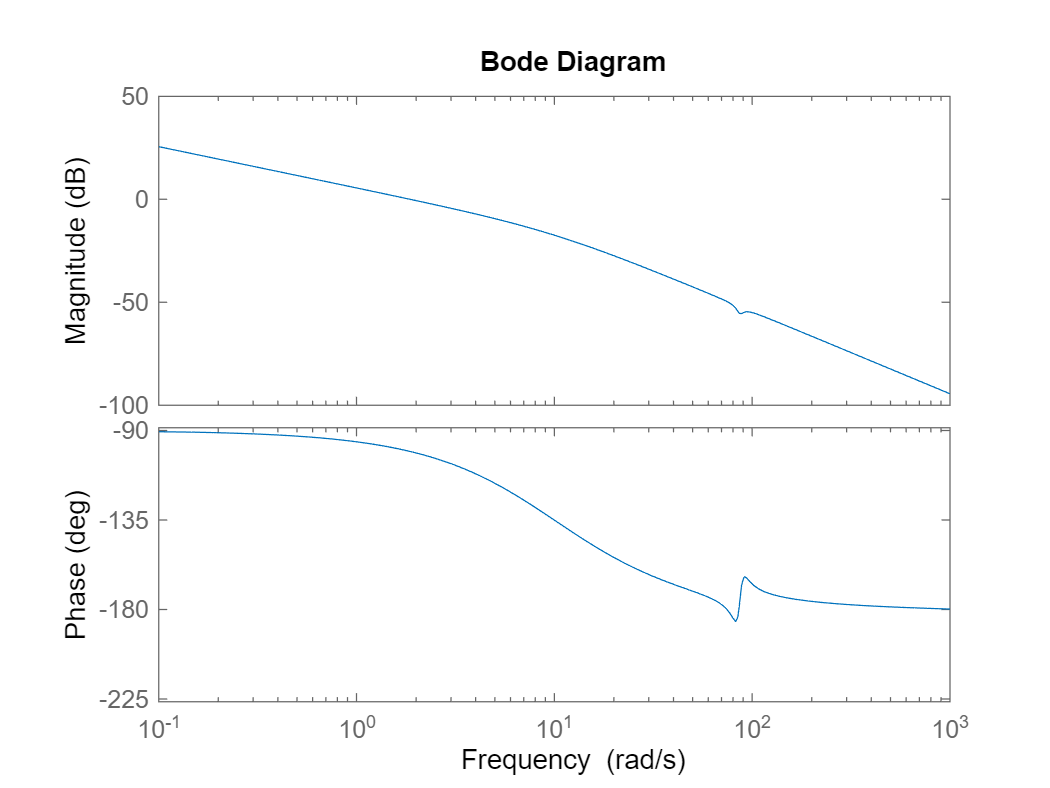

figure()
bode(sys1)

c)

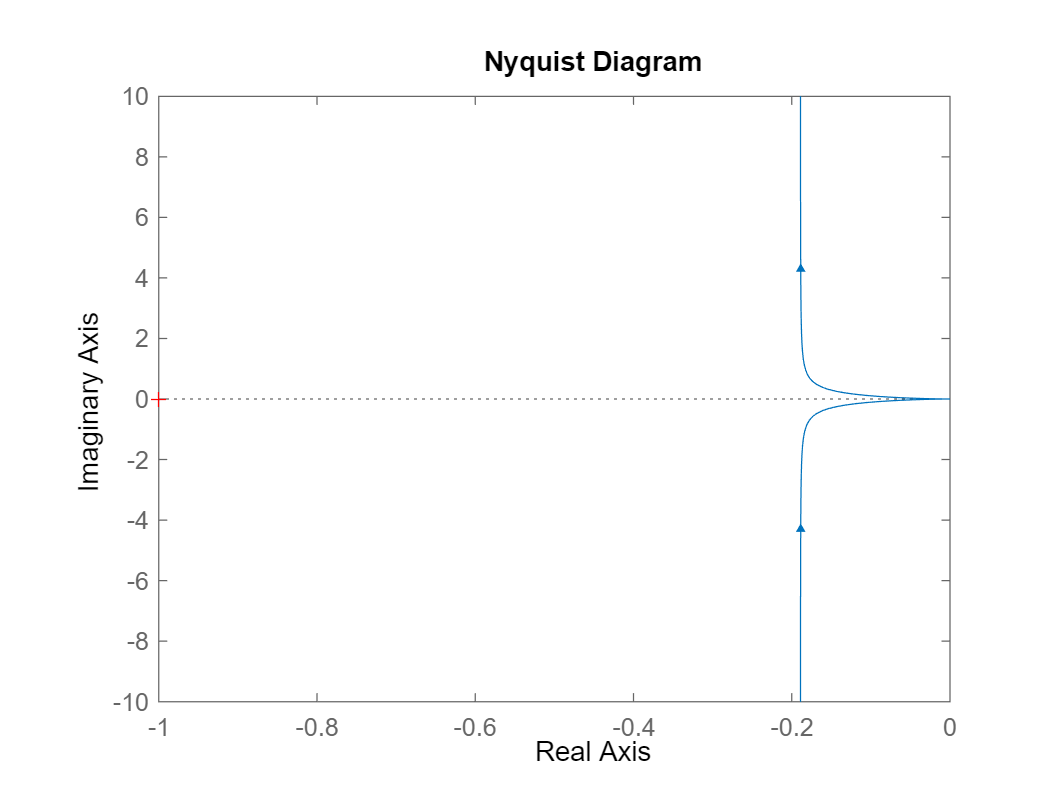

%plotting nyquist and rlocus
figure()
nyquist(sys1)

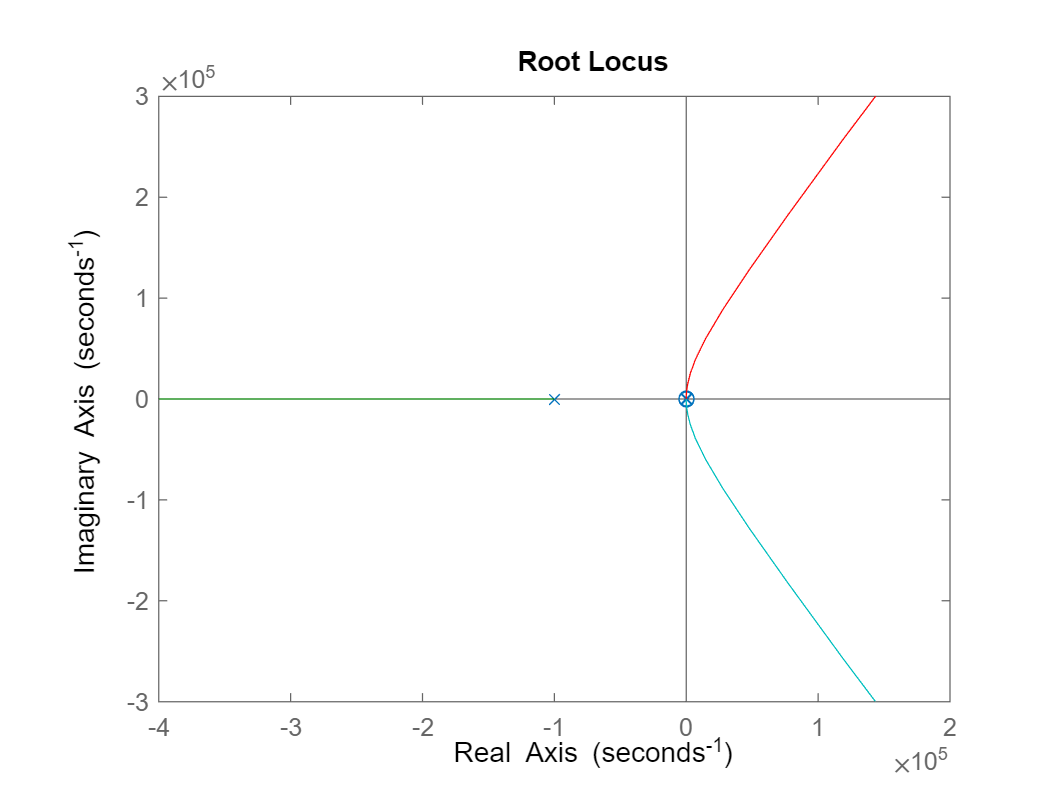

figure()
rlocus(sys1)

d)

%checking if variable state feedback can be designed
[Abar,Bbar,Cbar,T,k]=ctrbf(A,B,C(1,:))

Abar =    1.8605e-13  -8.6726e-13  -1.3417e-14   5.8057e-14  -4.9024e-16   3.2732e-16
    0.0015827       7.0951       2.1719   3.0011e-15   -1.212e-16   -6.884e-17
       2.3716      -3270.3      -768.84       415.22   1.4168e-15   1.8444e-16
       4.3069      -5944.3      -1397.3       755.18       2.8426   1.0347e-16
         2012       2025.6       2305.3      -1256.9      -18.017       3.5598
  -5.6569e+07   1.4563e+07  -4.7874e+07   2.6382e+07        93634       -1e+05


Bbar =   -6.5888e-15
  -6.4752e-14
   3.0875e-11
   5.6133e-11
   1.7085e-10
      5.7e+05


Cbar =       0.70711        0.183     -0.59834       0.3294            0            0


T =   -3.5355e-05      0.70711  -9.4281e-05   0.00070711  -1.1785e-09      0.70711
  -0.00035459        0.183  -0.00095531     -0.96611  -1.1941e-08     -0.18204
      0.16921     -0.59834      0.45126     -0.22664   5.6407e-06      0.59863
      0.30764       0.3294      0.82042      0.12354   1.0255e-05     -0.32939
      0.93634            0      -0.3511   3.5114e-06  -4.3888e-06            0
            0            0    -1.25e-05            0            1            0


k =      1     1     1     1     1     0


`[Abar,Bbar,Cbar,T,k] = ctrbf(A,B,C)` decomposes the state-space system represented by `A`, `B`, and `C` into the controllability staircase form, `Abar`, `Bbar`, and `Cbar`, described above. `T` is the similarity transformation matrix and `k` is a vector of length *n*, where *n* is the order of the system represented by `A`. Each entry of `k` represents the number of controllable states factored out during each step of the transformation matrix calculation. The number of nonzero elements in `k` indicates how many iterations were necessary to calculate `T`, and `sum(k)` is the number of states in *Ac*, the controllable portion of `Abar`.

## Task4

a)

%performing minimal realization
sys1_mreal=minreal(sys1)

sys1_mreal =
 
                 1.9e06 s^2 + 1.425e07 s + 1.425e10
  ----------------------------------------------------------------
  s^5 + 1e05 s^4 + 2.135e06 s^3 + 7.576e08 s^2 + 7.52e09 s + 1.099
 
Continuous-time transfer function.



%poles
P1_minreal=pole(sys1_mreal)

P1_minreal =        -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


%zeros
Z_minreal=zero(sys1_mreal)

Z_minreal =       -3.7501 +     86.523i
      -3.7501 -     86.523i


%[mag,phase,wout] = bode(sys1_mreal, logspace(-1,1,100))

b)

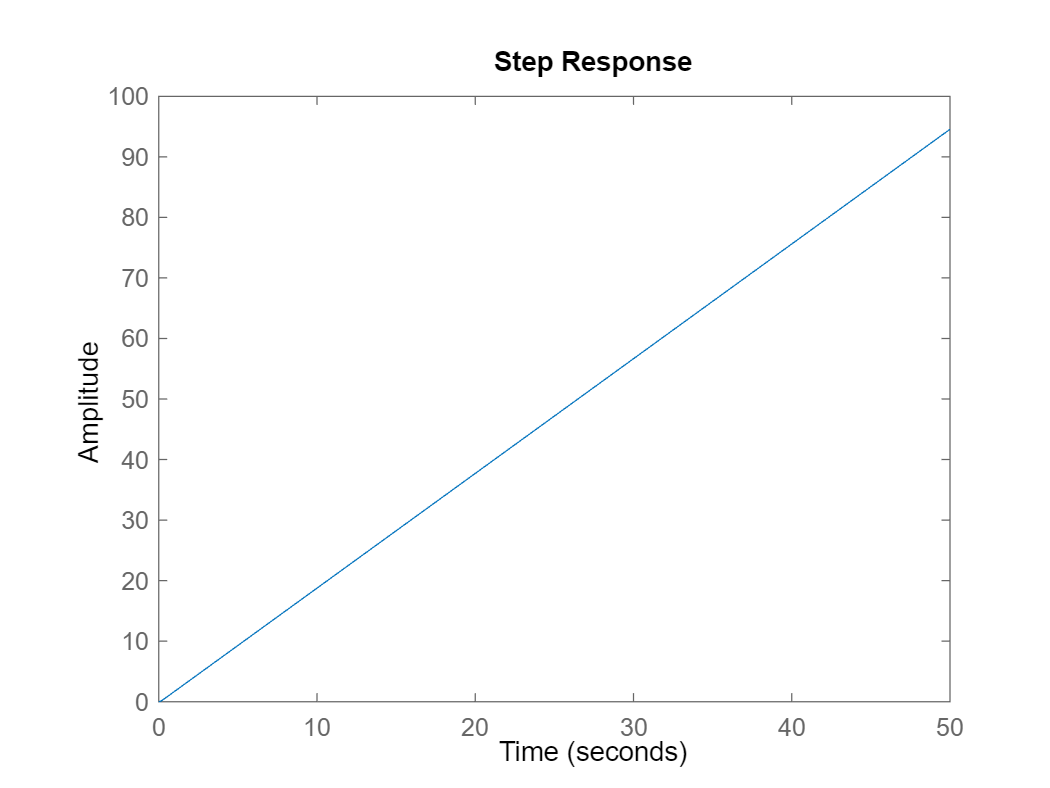

%checking behaviour of the minreal system
figure()
step(sys1_mreal)

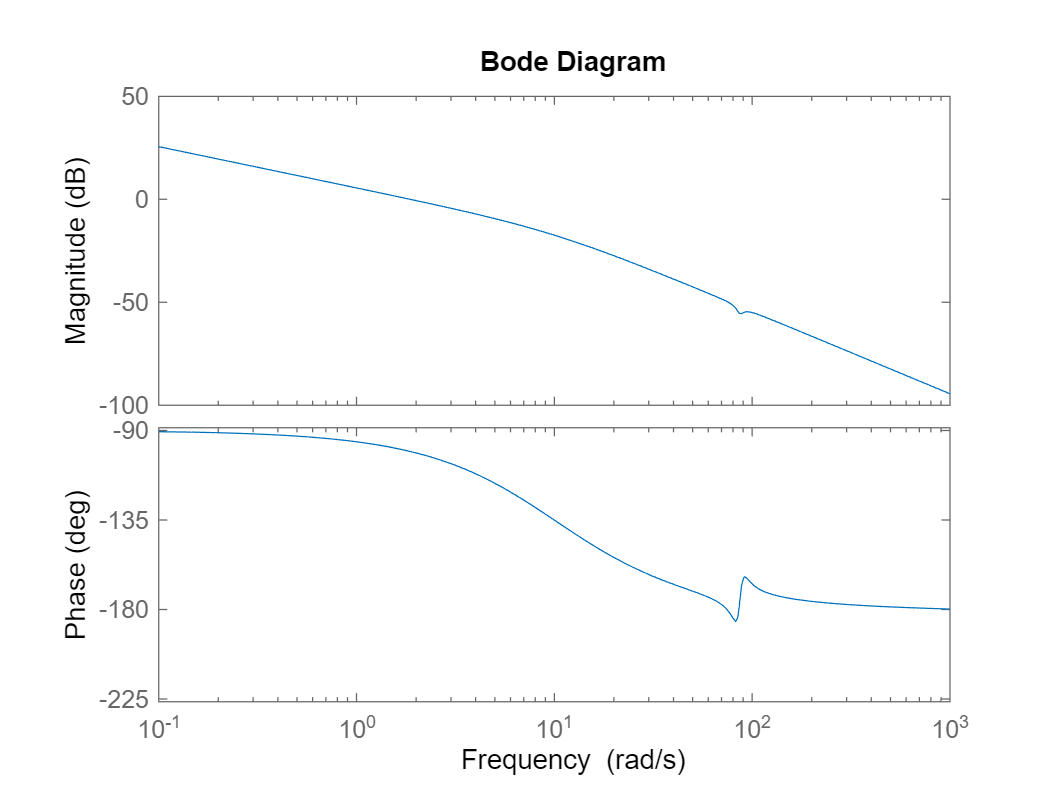

figure()
bode(sys1_mreal)

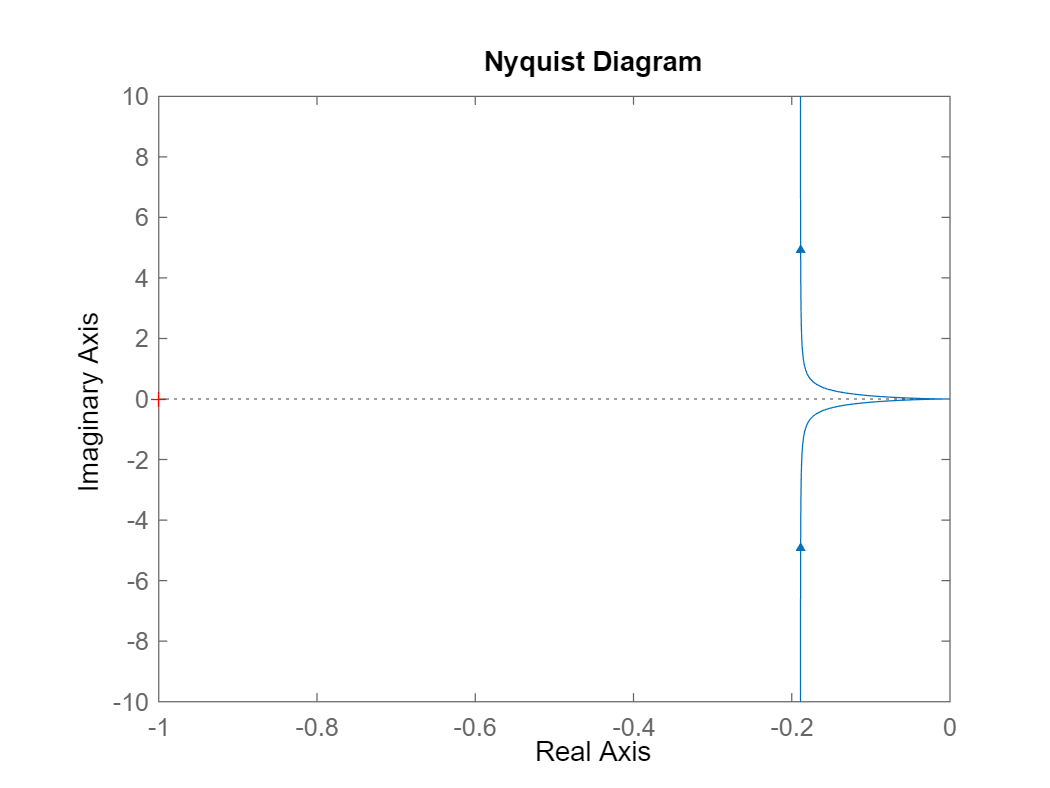

figure()
nyquist(sys1_mreal)

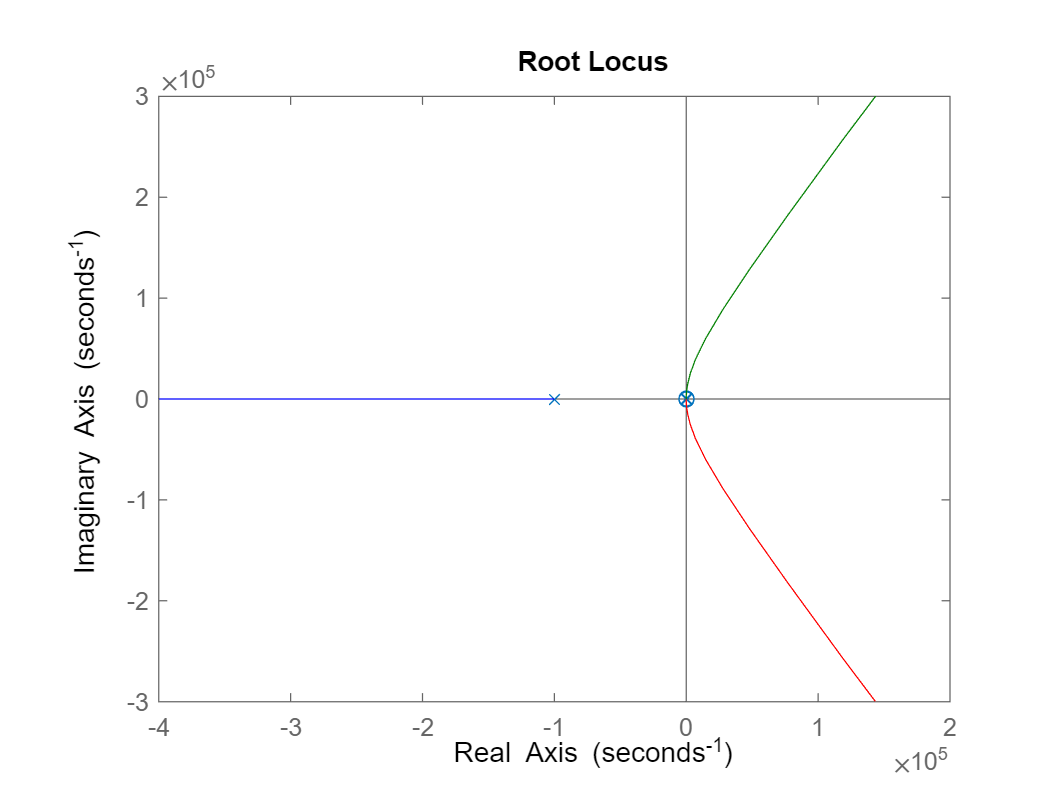

figure()
rlocus(sys1_mreal)

poles_min = pole(sys1_mreal)

poles_min =        -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


zeros_min = zero(sys1_mreal)

zeros_min =       -3.7501 +     86.523i
      -3.7501 -     86.523i


%eliminating a pole
dompoles = [0 -10.077 -5.5998+86.204i -5.5998-86.204i];
domzeros = [-3.7501+86.523i -3.7501-86.523i];
Num_new = poly(domzeros);
Den_new = poly(dompoles);
G4s=tf(Num_new,Den_new)

G4s =
 
            s^2 + 7.5 s + 7500
  --------------------------------------
  s^4 + 21.28 s^3 + 7575 s^2 + 7.52e04 s
 
Continuous-time transfer function.



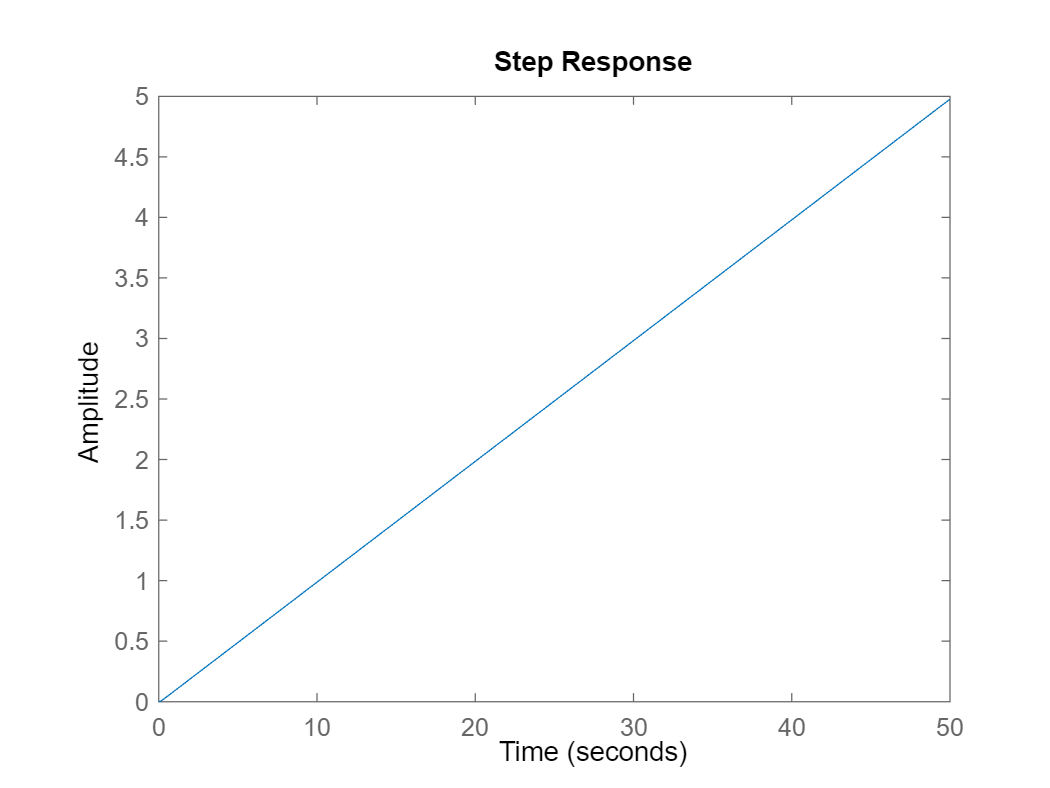

%s^4+21.28s^3+7575s^2+75200s
%checking behaviour of the minreal system
figure()
step(G4s)

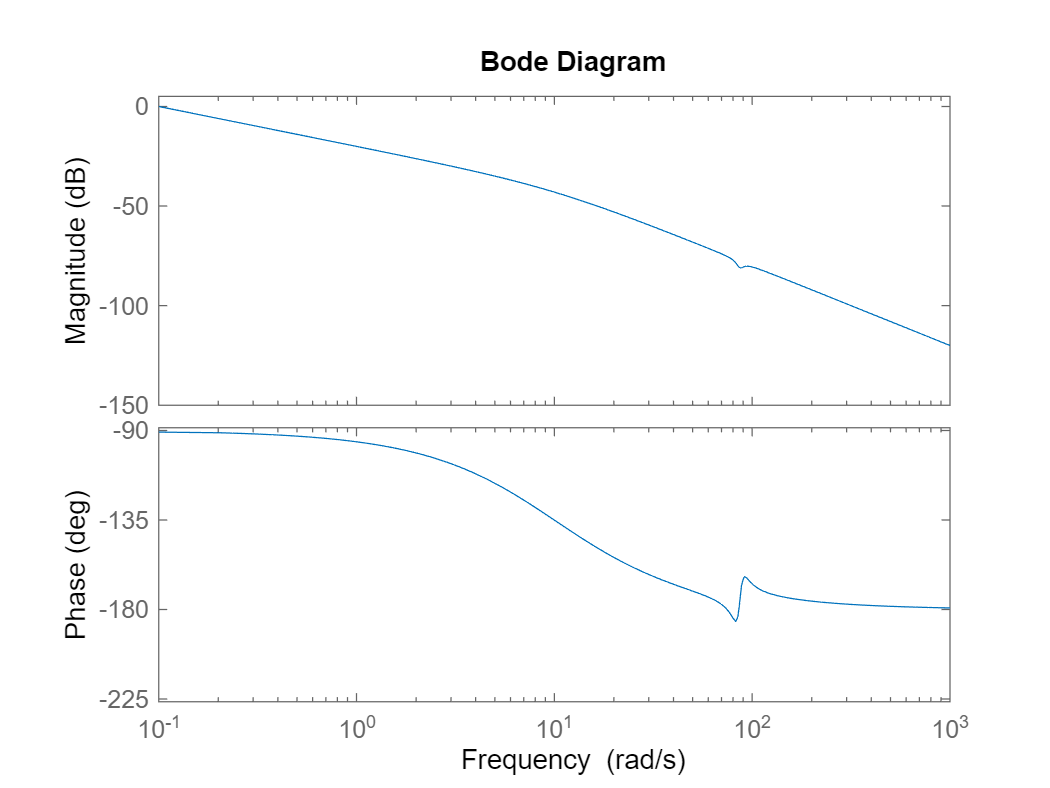

figure()
bode(G4s)

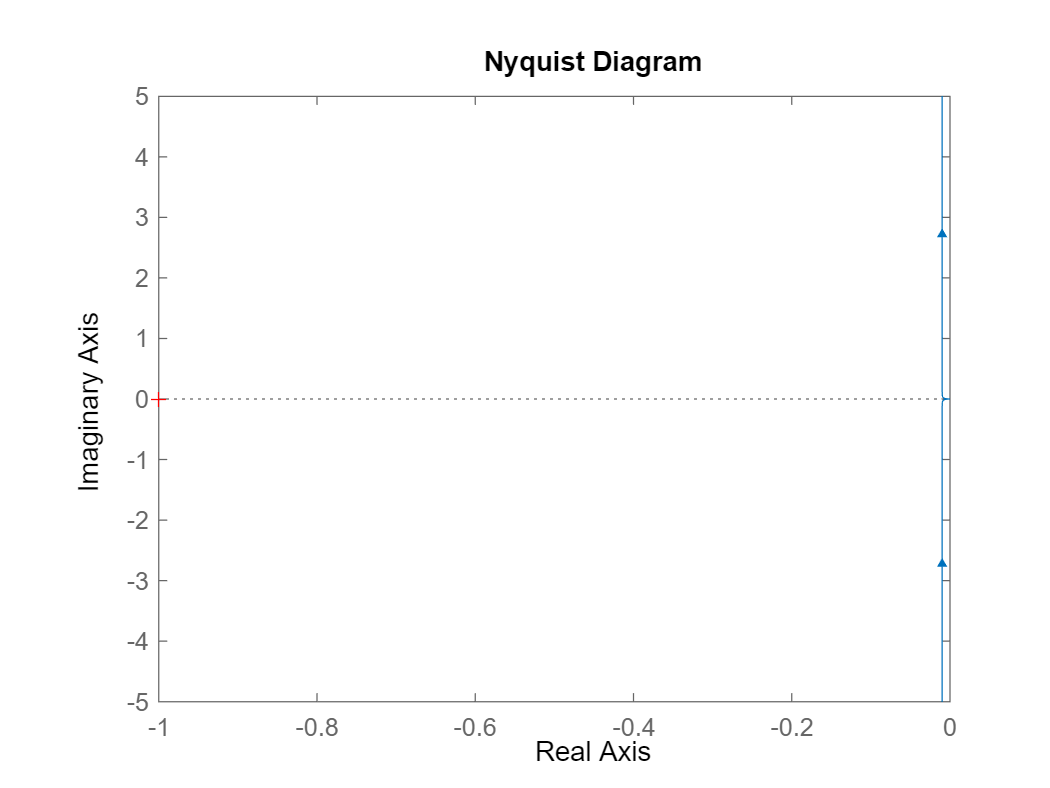

figure()
nyquist(G4s)

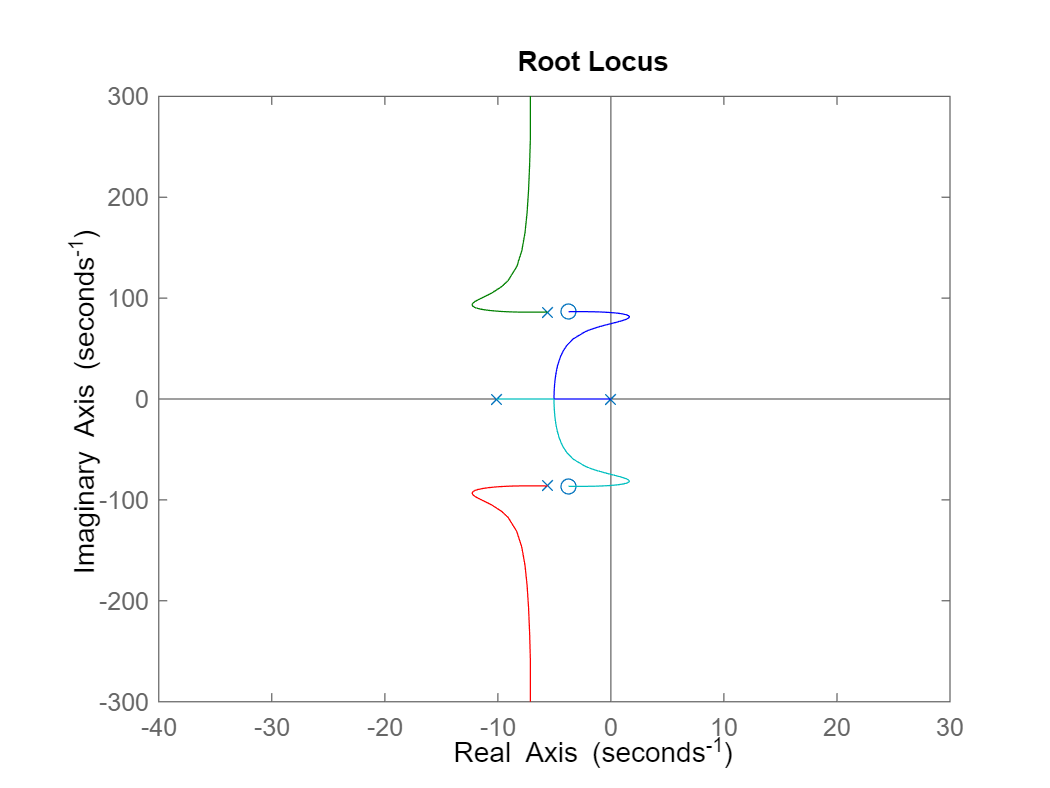

figure()
rlocus(G4s)

%[mag2,phase2,wout2] = bode(G4s, logspace(-1,1,100))

c)

Num_new=[1 7.5 7500]

Num_new =             1          7.5         7500


Den_new=[1 21.28 7575 75200 0]

Den_new =             1        21.28         7575        75200            0


G4s=tf(Num_new, Den_new)

G4s =
 
           s^2 + 7.5 s + 7500
  ------------------------------------
  s^4 + 21.28 s^3 + 7575 s^2 + 75200 s
 
Continuous-time transfer function.



[A_4,B_4,C_4,D_4] = tf2ss(Num_new, Den_new)

A_4 =        -21.28        -7575       -75200            0
            1            0            0            0
            0            1            0            0
            0            0            1            0


B_4 =      1
     0
     0
     0


C_4 =             0            1          7.5         7500


D_4 =      0


P4=pole(G4s)

P4 =             0 +          0i
      -5.6012 +     86.202i
      -5.6012 -     86.202i
      -10.078 +          0i


## Task5

a)

% Check the controllability and observability of the system
system_order = length(A_4) % equals "4"

system_order =      4


M = ctrb(A_4, B_4);
rank_of_M = rank(M)  % equals "4"

rank_of_M =      4


N = obsv(A_4, C_4);
rank_of_N = rank(N) % equals "4"

rank_of_N =      4


b)

damping = 0.707;
Ts=2;
OS=5;
wn=4/(damping*Ts)

wn =        2.8289


% Calculate desired pole locations
p1 = -damping * wn + 1i * wn * sqrt(1 - damping^2);
p2 = -damping * wn - 1i * wn * sqrt(1 - damping^2);
% For a fourth-order system, repeat the steps for the second set of poles
% p3 = conj(p1);
% p4 = conj(p2);
p3 = 10*p1;  %p3&p4 have to be at least 10 times bigger than the dominant poles
p4 = 10*p2;
% Define desired pole locations
desired_poles = [p1; p2; p3; p4];
% Calculate control gains
K = acker(A_4, B_4, desired_poles);
% Apply state feedback controller
sys_with_controller = ss(A_4 - B_4*K, B_4, C_4, D_4);
% Verify the closed-loop system poles
closed_loop_poles=eig(A_4 - B_4*K)

closed_loop_poles =           -20 +     20.006i
          -20 -     20.006i
           -2 +     2.0006i
           -2 -     2.0006i


eig(A_4)

ans =             0 +          0i
      -5.6012 +     86.202i
      -5.6012 -     86.202i
      -10.078 +          0i


disp("Control Gains (K):");

Control Gains (K):


disp(K);

        22.72      -6606.8       -71679       6403.9



disp("Closed-loop System Poles:");

Closed-loop System Poles:


disp(closed_loop_poles);

          -20 +     20.006i
          -20 -     20.006i
           -2 +     2.0006i
           -2 -     2.0006i



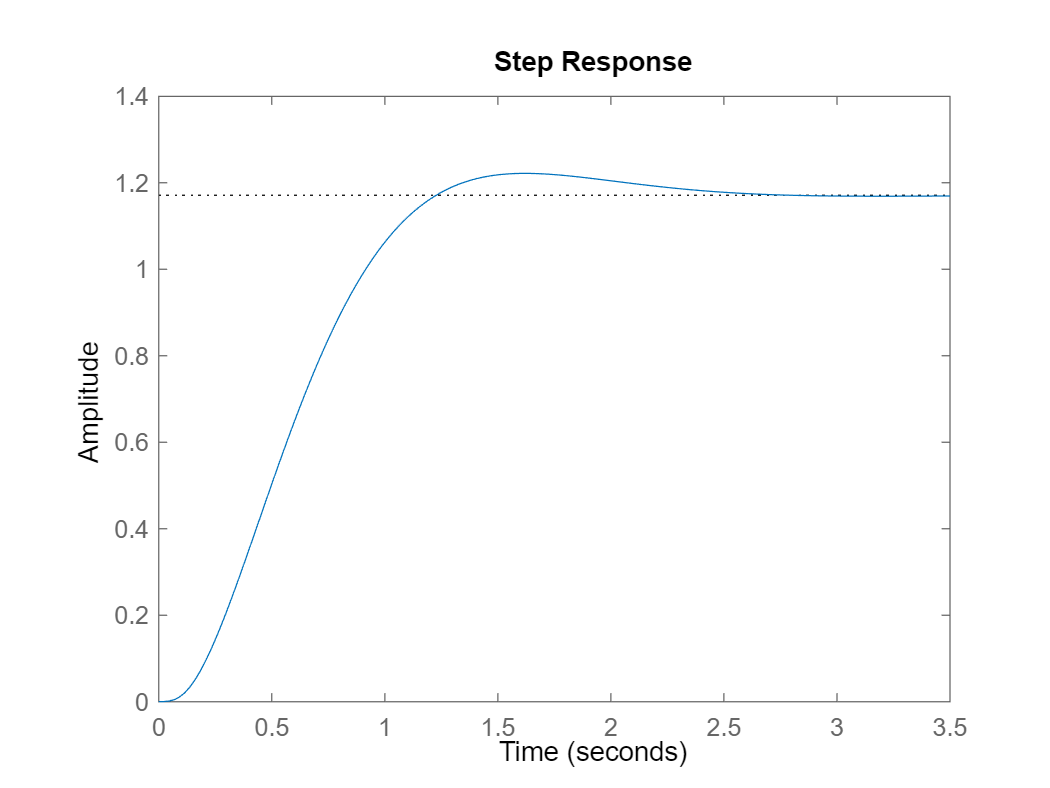


step(sys_with_controller)

sys_with_controller = ss(A_4 - B_4*K, B_4, C_4, D_4);

stepinfo(sys_with_controller)

ans = struct with fields:
         RiseTime: 0.75955
    TransientTime: 2.1571
     SettlingTime: 2.1571
      SettlingMin: 1.0561
      SettlingMax: 1.2218
        Overshoot: 4.3229
       Undershoot: 0
             Peak: 1.2218
         PeakTime: 1.6118


c)

Ae = [A_4 zeros(size(A_4(:,1))); C_4 zeros(size(C_4(:,1)))];% Ae = [Ag 0; Cg 0]
Be = [B_4; zeros(size(B_4(1,:)))];% Be = [Bg; 0]
Ce = [C_4 zeros(size(C_4(:,1)))];% Ce = [Cg 0]
De = [0];
%now system is 5x5 due to integral element
system_order = length(Ae)

system_order =      5


M = ctrb(Ae, Be);
rank_of_M = rank(M)

rank_of_M =      5


N = obsv(Ae, Ce);
rank_of_N = rank(N)

rank_of_N =      4


[num2,den2] = ord2(wn, damping);
dominant = roots(den2); % dominant complex pole pair

desiredpoles_ext = [dominant' 10*conj(dominant(1)) 10*conj(dominant(2)) 20*min(dominant)];

K_e = acker(Ae, Be, desiredpoles_ext)

K_e =        72.053      -4206.8       -17301   2.2399e+05        57.84


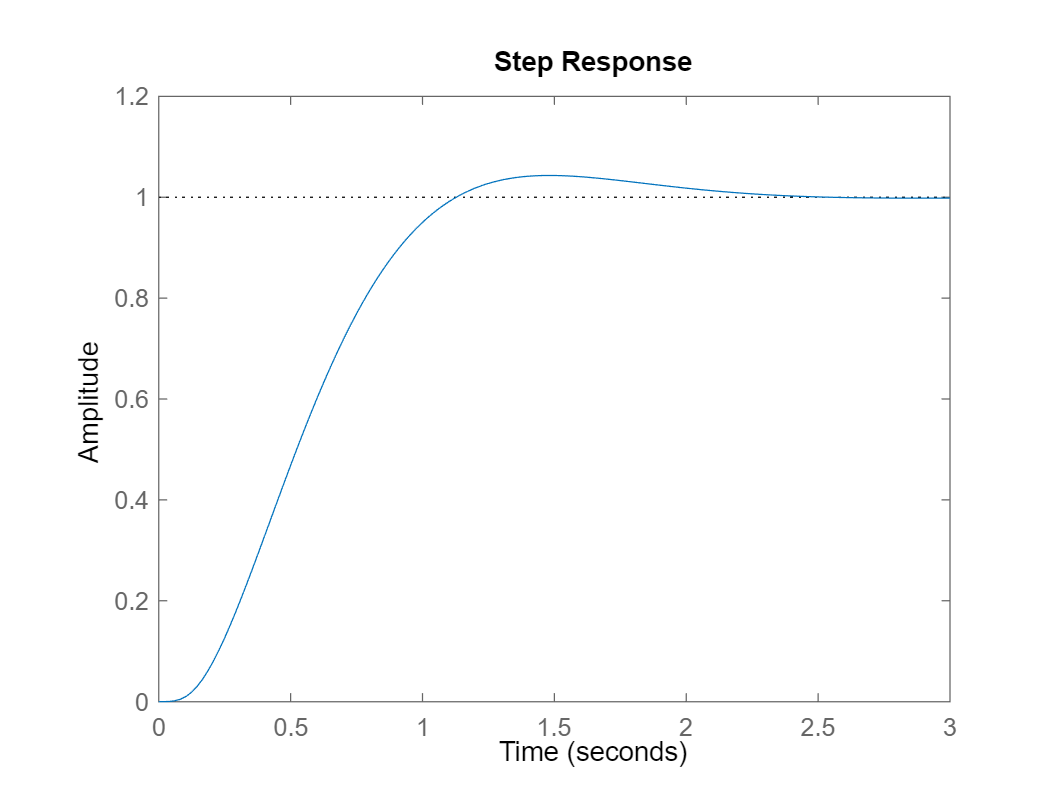

Asf_ext = Ae - Be * K_e;
[numsf_ext, densf_ext] = ss2tf(Asf_ext,  [0; 0; 0; 0; -1], Ce, De);
SYS_ext = tf(numsf_ext, densf_ext);
step(SYS_ext)

stepinfo(SYS_ext)

ans = struct with fields:
         RiseTime: 0.68555
    TransientTime: 1.9641
     SettlingTime: 1.9641
      SettlingMin: 0.90009
      SettlingMax: 1.0431
        Overshoot: 4.3092
       Undershoot: 0
             Peak: 1.0431
         PeakTime: 1.4714


## Task6

[num2,den2] = ord2(wn,damping);
dominant = roots(den2)

dominant =       -2.2222 +     2.2229i
      -2.2222 -     2.2229i


desiredpoles = [dominant' 16 * real( dominant(1)) 16 *real(dominant(1))];
K = acker(A_4,B_4,desiredpoles)

K =        54.276      -5984.9       -68879        12490


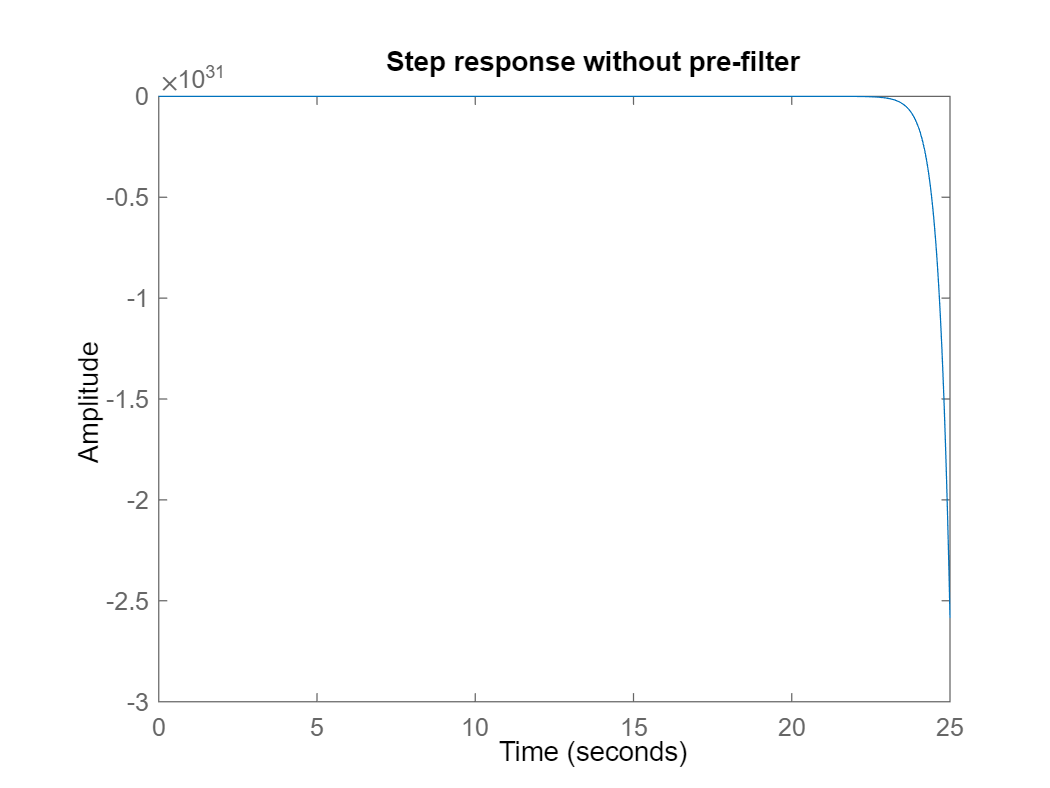

op = [1 2.8*wn 5*wn^2 5.5*wn^3 3.4*wn^4 wn^5];
% PID constants
Kp = 0.0366;
Ki = 0.0324;
Kd = -12.88;
% calculating the closed loop transfer function
closedtf = tf([Kd Kp Ki],[1 0]);
noprefilter = feedback(G4s*closedtf,1);
prefilter = tf(1e6,[1 28.46 7735 1.516e5 7.54e5 1.001e6]);
% plotting results
figure(1)
step(noprefilter);
title('Step response without pre-filter');

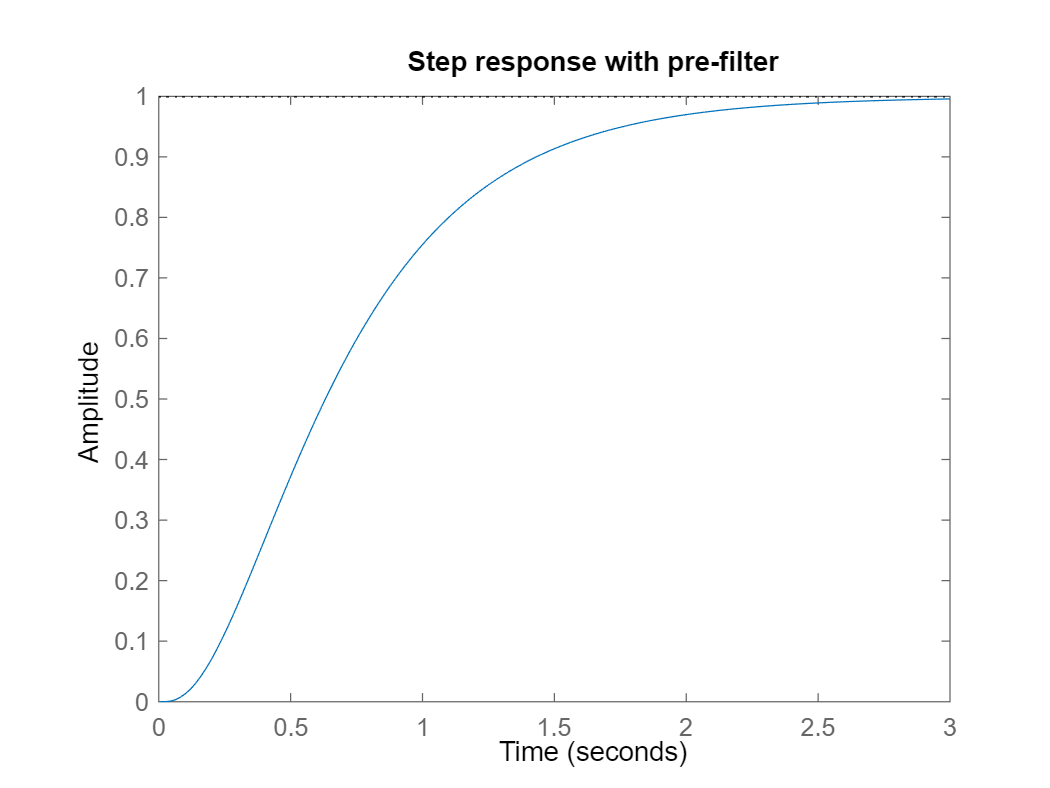

figure(2)
step(prefilter);
title('Step response with pre-filter');